# Regimizing Gemm Step 5

This Live Script helps you visualize the performance of a second implementation of matrix-matrix multiplication in GemmIJSapdot4x1Reg.c.  It takes the inner-most loop and implements it as a call to a subroutine that updates the (i,j) element of C with the dot product of the ith row of A with the jth column of B.  This time, four consecutive elements of C are updated at a time:  C(i,j), C(i+1,j), C(i+2,j), C(i+3,j).  Importantly, these elements are accumulated into registers and elements of the column of B are also explicitly placed in registers.

To gather the performance data, execute 

clear
system('make test_step_5')

gcc -O0 -Wall -I/Users/rvdg/blis/include/blis -m64 -msse3 -std=c99   -c -o driver_step_5.o driver_step_5.c
gcc -O0 -Wall -I/Users/rvdg/blis/include/blis -m64 -msse3 -std=c99   -c -o GemmIJSapdot4x1Reg.o GemmIJSapdot4x1Reg.c
GemmIJSapdot4x1Reg.c:28:19: warning: unused variable 'c0' [-Wunused-variable]
  register double c0=0.0, c1=0.0, c2=0.0, c3=0.0, ycur;
                  ^
GemmIJSapdot4x1Reg.c:28:27: warning: unused variable 'c1' [-Wunused-variable]
  register double c0=0.0, c1=0.0, c2=0.0, c3=0.0, ycur;
                          ^
GemmIJSapdot4x1Reg.c:28:35: warning: unused variable 'c2' [-Wunused-variable]
  register double c0=0.0, c1=0.0, c2=0.0, c3=0.0, ycur;
                                  ^
GemmIJSapdot4x1Reg.c:28:43: warning: unused variable 'c3' [-Wunused-variable]
  register double c0=0.0, c1=0.0, c2=0.0, c3=0.0, ycur;
                                          ^
4 warnings generated.
gcc driver_step_5.o GemmIJSapdot4x1Reg.o  FLA_Clock.o MaxAbsDiff.o RandomMatrix.o /Users/r

ans = 0

When completed, this creates output file 'data_step_3.m' with timing data.  This Life Script then creates graphs from that timing data.

## Step 1a: Load timing data

First, load the timing data from Steps 1-5.  

data_step_1
data_step_2
data_step_3
data_step_4
data_step_5

## Step 1b: Make sure you are getting the right answer

MaxAbsDiff = max( abs( data_GemmIJSapdot4x1Reg( :, 3 ) ) )

MaxAbsDiff = 3.4106e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Step 1c: Plot the timing data.

The first graph shows the execution time of the different implementations as a function of the matrix size $n$.

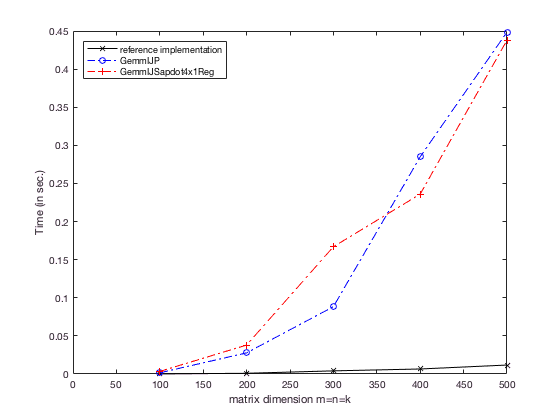

close all

% Plot the reference implementation performance
plot( data_ref( :,1 ), data_ref( :, 2 ), 'k-x' ); 

hold on    % Plot additional data in same figure

plot( data_GemmIJP( :,1 ), data_GemmIJP( :, 2 ), 'b-.o' ); 
plot( data_GemmIJSapdot4x1Reg( :,1 ), data_GemmIJSapdot4x1Reg( :, 2 ), 'r-.+' ); 

hold off   % Stop plotting additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Time (in sec.)' );
legend( 'reference implementation', ...
        'GemmIJP', ...
        'GemmIJSapdot4x1Reg', ...
        'Location', 'NorthWest' );

% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

We plot 

- the speedup of GemmIJSapdot4x1Reg relative to GemmIJP.

- the speedup of the highly Regimized reference implementation relative to GemmIJSapdot4x1Reg.

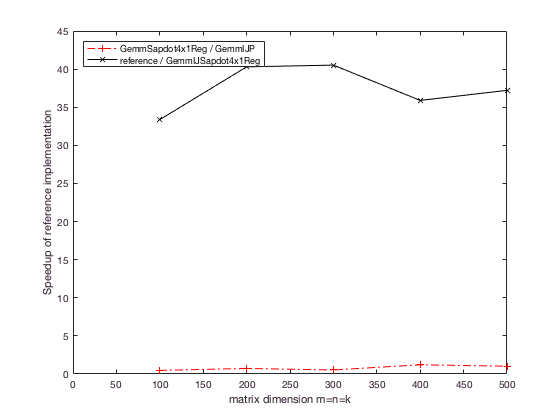

plot( data_GemmIJP( :,1 ), data_GemmIJP( :, 2 ) ./ data_GemmIJSapdot4x1Reg( :, 2 ), 'r-.+' ); 

hold on    % Plot additional data in same figure

plot( data_ref( :,1 ), data_GemmIJSapdot4x1Reg( :, 2 ) ./ data_ref( :, 2 ), 'k-x' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Speedup of reference implementation' );
legend( 'GemmSapdot4x1Reg / GemmIJP', ...
        'reference / GemmIJSapdot4x1Reg', ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Step 3: Plot performance.

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.

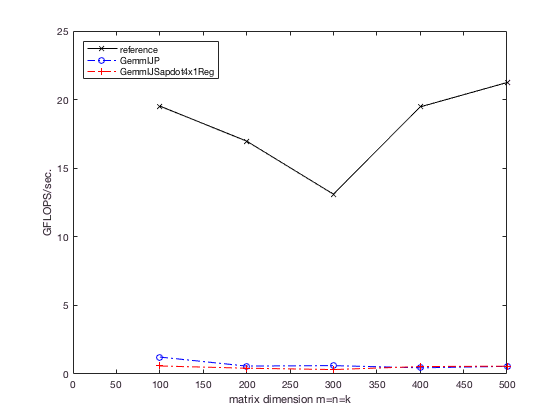

ns = data_ref( :, 1 );                                   % Extract a vector of matrix size.
gflops = 2.0 * ns.^3 ./ data_ref( :, 2 ) * 1.0e-9;    % Compute a vector of corresponding 
                                                           % GFLOPS/sec from the timing data.
plot( ns, gflops, 'k-x' );                                      % Plot the performance data

hold on

ns = data_GemmIJP( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmIJP( :, 2 ) * 1.0e-9;
plot( ns, gflops, 'b-.o' ); 

ns = data_GemmIJSapdot4x1Reg( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmIJSapdot4x1Reg( :, 2 ) * 1.0e-9;
plot( ns, gflops, 'r-.+' ); 

xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS/sec.' );
legend( 'reference', ...
        'GemmIJP', ...
        'GemmIJSapdot4x1Reg', ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Conclusion

By casting the inner most loop in terms of a call to a routine that performs the dot product, we don't observe much (if any at all) of a performance improvement.  But, again, this is only a step along the way.